clc
clearvars
close all

data_dir1 = fullfile(pwd,"data/hra/control/");
data_dir2 = fullfile(pwd,"data/hra/dementia/");

fnames_hc = dir(data_dir1);
fnames_hc = fnames_hc(~ismember({fnames_hc.name},{'.','..'}));
fnames_ad = dir(data_dir2);
fnames_ad = fnames_ad(~ismember({fnames_ad.name},{'.','..'}));

num_id = 32;

## Plot sample data

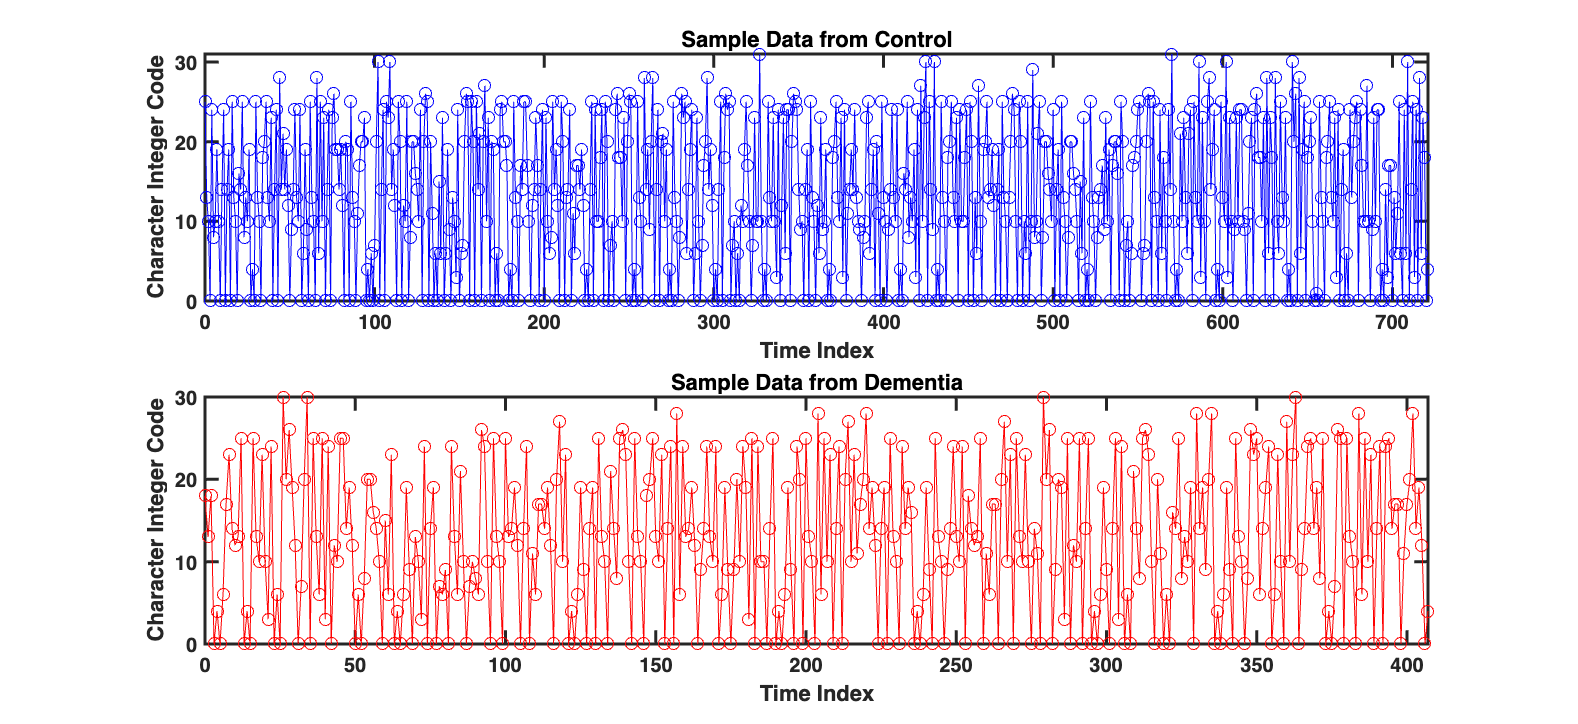

x1 = readtable(fullfile(data_dir1,fnames_hc(1).name));
x2 = readtable(fullfile(data_dir2,fnames_ad(1).name));

figure('Color','w','Position',[100,100,1200,550])
subplot(2,1,1)
plot(x1.index,x1.x,'-o','Color','blue')
axis tight
title("Sample Data from Control")
xlabel("Time Index")
ylabel("Character Integer Code")
set(gca,'FontWeight','bold','LineWidth',1.5)

subplot(2,1,2)
plot(x2.index,x2.x,'-o','Color','red')
axis tight
title("Sample Data from Dementia")
xlabel("Time Index")
ylabel("Character Integer Code")
set(gca,'FontWeight','bold','LineWidth',1.5)

for i=0:(num_id-1)
    id_idx = find(x1.x == i);
    s = sprintf('ID %i: %i', i+1, length(id_idx));
    disp(s)
end

ID 1: 150
ID 2: 1
ID 3: 0
ID 4: 9
ID 5: 17
ID 6: 0
ID 7: 31
ID 8: 8
ID 9: 11
ID 10: 13
ID 11: 80
ID 12: 7
ID 13: 12
ID 14: 38
ID 15: 44
ID 16: 2
ID 17: 6
ID 18: 15
ID 19: 16
ID 20: 32
ID 21: 44
ID 22: 6
ID 23: 0
ID 24: 35
ID 25: 46
ID 26: 62
ID 27: 12
ID 28: 4
ID 29: 10
ID 30: 1
ID 31: 8
ID 32: 2


for i=0:(num_id-1)
    id_idx = find(x2.x == i);
    s = sprintf('ID %i: %i', i+1, length(id_idx));
    disp(s)
end

ID 1: 85
ID 2: 0
ID 3: 0
ID 4: 6
ID 5: 10
ID 6: 0
ID 7: 24
ID 8: 4
ID 9: 7
ID 10: 14
ID 11: 35
ID 12: 6
ID 13: 11
ID 14: 22
ID 15: 31
ID 16: 1
ID 17: 3
ID 18: 9
ID 19: 4
ID 20: 24
ID 21: 16
ID 22: 3
ID 23: 0
ID 24: 15
ID 25: 22
ID 26: 34
ID 27: 7
ID 28: 4
ID 29: 7
ID 30: 0
ID 31: 4
ID 32: 0


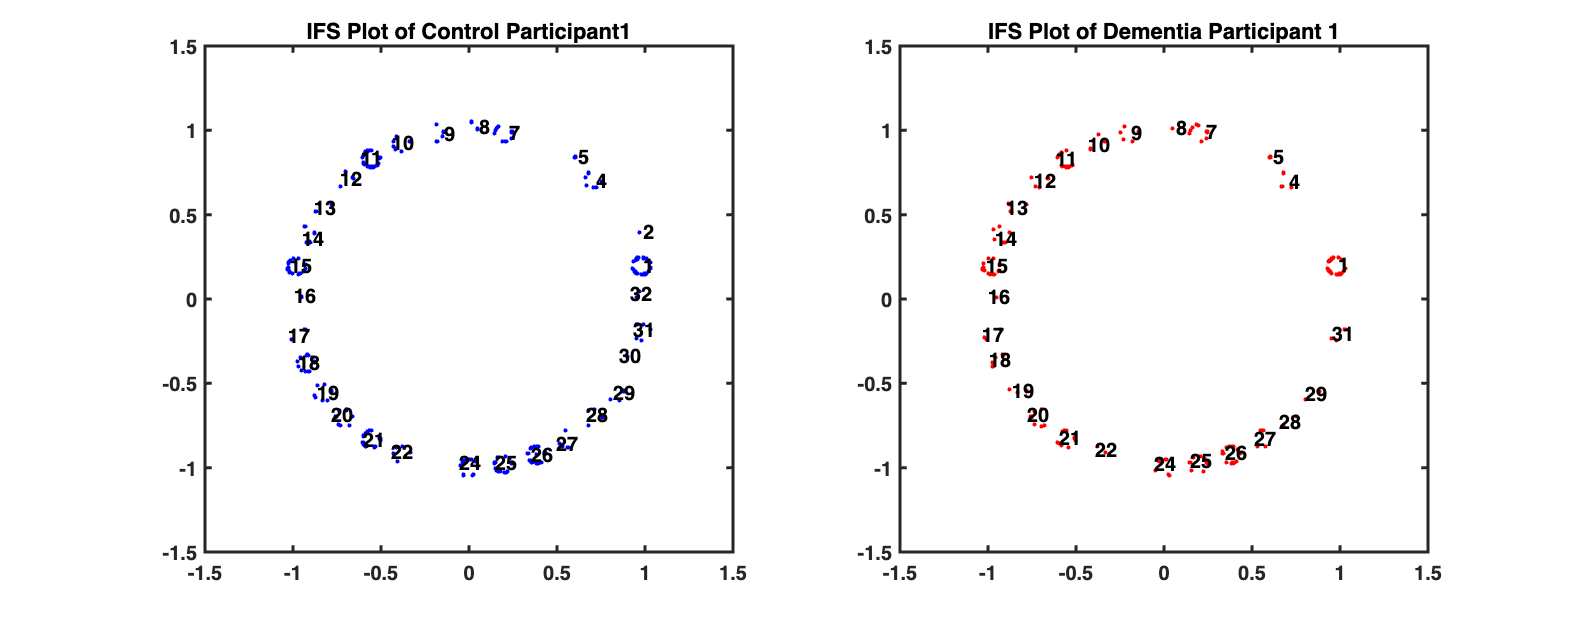

alpha = 0.05;
sig1 = x1.x + 1;
ifs_hc = IFS(sig1,num_id,alpha);
sig2 = x2.x + 1;
ifs_ad = IFS(sig2,num_id,alpha);
ifs_hc(1,:) = [];
ifs_ad(1,:) = [];

figure('Color','w','Position',[0,0,1400,550]);
subplot(1,2,1)
plot(ifs_hc(:,1),ifs_hc(:,2),'.','Color','b')
for i=1:num_id
    id_idx = find(sig1 == i);
    c = mean(ifs_hc(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')
end
title('IFS Plot of Control Participant1')
set(gca,'LineWidth',1.5,'FontWeight','bold')
subplot(1,2,2)
plot(ifs_ad(:,1),ifs_ad(:,2),'.','Color','r')
for i=1:num_id
    id_idx = find(sig2 == i);
    c = mean(ifs_ad(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')
end
title('IFS Plot of Dementia Participant 1')
set(gca,'LineWidth',1.5,'FontWeight','bold')

## Quantifications of IFS patterns

fsize1 = size(fnames_hc,1);
fsize2 = size(fnames_ad,1);
feat_mx = NaN(fsize1+fsize2,32*3+32*32*3);

alpha = 0.04;
nbins = 0;

for i=1:fsize1
%     out = sprintf("HC File [%i/%i]", i, fsize2);
%     disp(out);
    
    csig = readtable(fullfile(data_dir1,fnames_hc(i).name));
    csig = csig.x + 1;
    ifs_add = IFS(csig,num_id,alpha);
    
    % 1st order
    for j=1:num_id
        [feat_mx(i,j),feat_mx(i,j+num_id),feat_mx(i,j+num_id*2)] = ...
            heterorecurrence(ifs_add,csig,j,nbins);
        % 2nd order
        for k=1:num_id
            [feat_mx(i,k+96*j),feat_mx(i,k+96*j+num_id),feat_mx(i,k+96*j+num_id*2)] = ...
                heterorecurrence2(ifs_add,csig,j,k);
        end
    end
end

for i=1:fsize2
%     out = sprintf("AD File [%i/%i]", i, fsize2);
%     disp(out)

    csig = readtable(fullfile(data_dir2,fnames_ad(i).name));
    csig = csig.x + 1;
    ifs_add = IFS(csig,num_id,alpha);

    % 1st order
    for j=1:num_id
        [feat_mx(fsize1+i,j),feat_mx(fsize1+i,j+num_id),feat_mx(fsize1+i,j+num_id*2)] = ...
            heterorecurrence(ifs_add,csig,j,nbins);
        % 2nd order
        for k=1:num_id
            [feat_mx(fsize1+i,k+96*j),feat_mx(fsize1+i,k+96*j+num_id),feat_mx(fsize1+i,k+96*j+num_id*2)] = ...
                heterorecurrence2(ifs_add,csig,j,k);
        end
    end
end

# Variable screening (PCA/KS Test)

clc
close all
clearvars

load(fullfile(pwd,"data","hra","hrq_mx.mat"))
num_id = 32;

PCA without removing zero columns

w = 1./(var(feat_mx)+eps);
[~,score,~,~,explained] = pca(feat_mx,'VariableWeights',w);

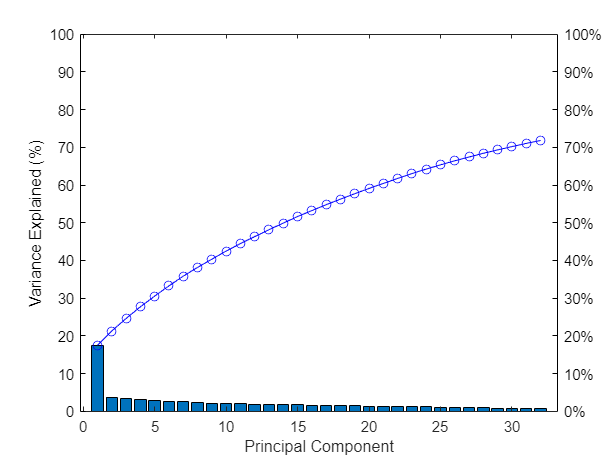

percent_ticks = string(0:10:100);
for i=1:length(percent_ticks)
    percent_ticks(i) = strcat(percent_ticks(i),"%");
end

figure
yyaxis left
bar(explained(1:num_id))
ylim([0,100])
set(get(gca,'YLabel'), 'String','Variance Explained (%)')
set(gca, 'YColor','black')
yyaxis right
plot(1:num_id,cumsum(explained(1:num_id)),'o-','Color','blue')
ylim([0,100])
yticklabels(percent_ticks)
set(gca, 'YColor','black')
xlabel('Principal Component')

## Remove zeros columns and perform the KS test

zidx = all(feat_mx==0,1);
feat_mx(:,zidx) = [];
num_hc = 243;

out_mx = NaN(size(feat_mx,2),4);
out_mx(:,4) = find(~zidx)';
for i=1:size(feat_mx,2)
    [out_mx(i,1),out_mx(i,2),out_mx(i,3)] = kstest2(feat_mx(1:num_hc,i),feat_mx(num_hc+1:end,i), ...
        'Alpha',0.05,'Tail','unequal');
end

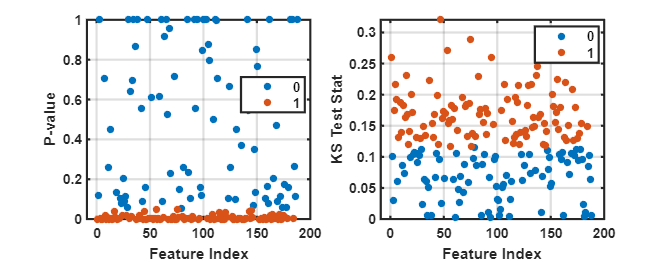

g = categorical(out_mx(:,1));
cidx = 1:size(feat_mx,2);

f = figure('Color','w','Position',[0,0,980,385]);
subplot(1,2,1)
gscatter(cidx,out_mx(:,2),g)
grid on
xlabel("Feature Index")
ylabel("P-value")
set(gca,'FontWeight','bold','LineWidth',1.5)

subplot(1,2,2)
gscatter(cidx,out_mx(:,3),g)
grid on
xlabel("Feature Index")
ylabel("KS Test Stat")
set(gca,'FontWeight','bold','LineWidth',1.5)

disp(out_mx(out_mx(:,3)>0.2,4)')

  Columns 1 through 8

           1           5          15          20          37          47          53          77

  Columns 9 through 16

          84          97         485         905        1196        1293        1455        1487

  Columns 17 through 20

        1940        2069        2360        2554



## Visualization of the distributional differneces of features

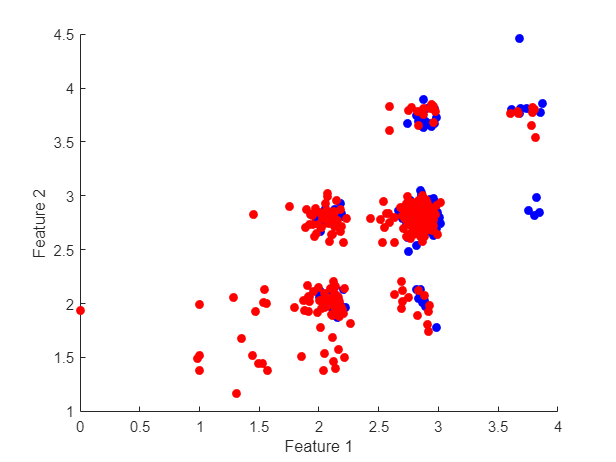

[~,max_idx] = maxk(out_mx(:,3),4);
i1 = max_idx(1);
i2 = max_idx(3);
figure('Color','w')
scatter(feat_mx(1:num_hc,i1),feat_mx(1:num_hc,i2),'filled','MarkerFaceColor','b')
hold on
scatter(feat_mx((num_hc+1):end,i1),feat_mx((num_hc+1):end,i2),'filled','MarkerFaceColor','r')
hold off
xlabel("Feature 1")
ylabel("Feature 2")

% feat_mx2 = feat_mx(:,out_mx(:,1) == 1);